## ECE 537 : Assignment 2

Group 9 - Ashlynn Steeves, Derrell D'Souza

close all;
clear all;
clc;

**Task 1** - Reload the Class A, B and C data from Exercise 1 and generated the Bayes decision boundaries for equal a priori class probabilities.

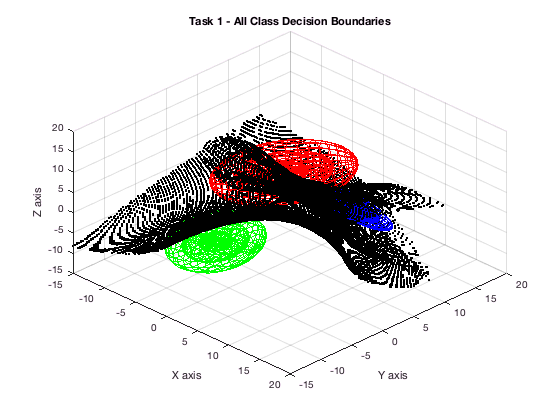

K = 1000;
D = 3;

% Dataset A
mu_A = [0 4 7];
sigma_A = [6.5000 2.1651 1.2500 ; 2.1651 5.1250 2.3816;1.2500 2.3816 2.3750];
data_A = gaussian_data_from_ss(K,D,mu_A,sigma_A);

% Dataset B
mu_B = [10 5 5];
sigma_B = [3.0184 0.4331 -1.4481; 0.4331 0.9436 -0.6456 ;-1.4481 -0.6456 1.2880];
data_B = gaussian_data_from_ss(K,D,mu_B,sigma_B);

% Dataset C
mu_C = [-2 -5 -5];
sigma_C = [6.8928 -1.3750 3.1945 ;-1.3750 3.3572 0.6945;3.1945 0.6945 3.7500];
data_C = gaussian_data_from_ss(K,D,mu_C,sigma_C);

Vaxis = [-15 15 -15 15 -15 15];
volume = vol3D(Vaxis, 200);

pdfA = gaus_pdf(data_A, volume); % A vector of probabilities that each point is from Class A
pdfB = gaus_pdf(data_B, volume); % A vector of probabilities that each point is from Class B
pdfC = gaus_pdf(data_C, volume); % A vector of probabilities that each point is from Class C

t1_priors = [1/3 1/3 1/3]; % Apriori probabilites for each class 
[t1_gA, t1_gB, t1_gC] = discriminant(pdfA, pdfB, pdfC, t1_priors);

[t1_b_AB, t1_b_BC, t1_b_CA] = boundaries(t1_gA, t1_gB, t1_gC,volume);
figure(1)
visualize_boundary(data_A, data_B, data_C, t1_b_AB, t1_b_BC, t1_b_CA);
title('Task 1 - All Class Decision Boundaries')

**Task 2** - Assess the degree to which changes to the means and covariance of the data classes produces changes the nature of the generated inter-class Bayes decision boundaries.

Solution:

A draw from a normal population tends to fall in a single cluster whose center is determined by the mean of the cluster and shape is determined by the covariance, the principal axes are given by the eigen vector of the covariance matrix with its length given by the square root of the corrsponding eigen values. Since boundaries are infact statistics of the datasets, which means their mean and covariance would affect the nature of the boundary changes to the mean and covarriance of a dataset may have dirastic impact on the nature of the generated inter-class Bayes decision boundaries. Please reffer to the plots generated in task 3 as further proof. 

**Task 3 **- Show the nature of these changes by plotting the 3 data classes and their respective decision boundaries with the same 3-D plot.

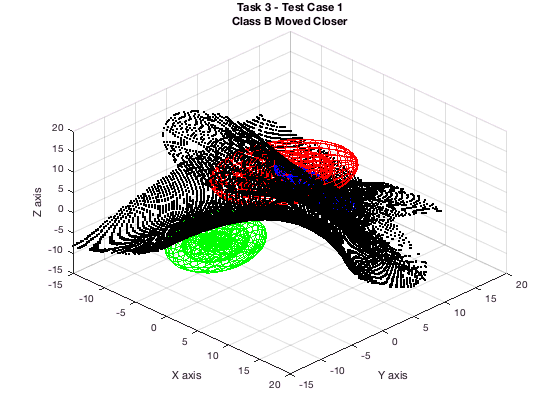

% Test Case 1
% Moving class B closer to class A by changing its mean

t3_1_mu_B = [5 4 7];
t3_1_data_B = gaussian_data_from_ss(K,D,t3_1_mu_B,sigma_B); % Re generating Class B with new mean
t3_1_pdfB = gaus_pdf(t3_1_data_B,volume); % A vector of probabilities that each point is from the new class B

t3_priors = [1/3, 1/3, 1/3];
[t3_1_gA, t3_1_gB, t3_1_gC] = discriminant(pdfA, t3_1_pdfB, pdfC, t3_priors);
[t3_1_b_AB, t3_1_b_BC, t3_1_b_CA] = boundaries(t3_1_gA, t3_1_gB, t3_1_gC,volume);

figure(2)
visualize_boundary(data_A, t3_1_data_B, data_C, t3_1_b_AB, t3_1_b_BC, t3_1_b_CA);
title({'Task 3 - Test Case 1', 'Class B Moved Closer'})


clear t3_1_data_B t3_1_pdfB t3_priors t3_1_gA t3_1_gB t3_1_gC t3_1_b_AB t3_1_b_BC t3_1_b_CA

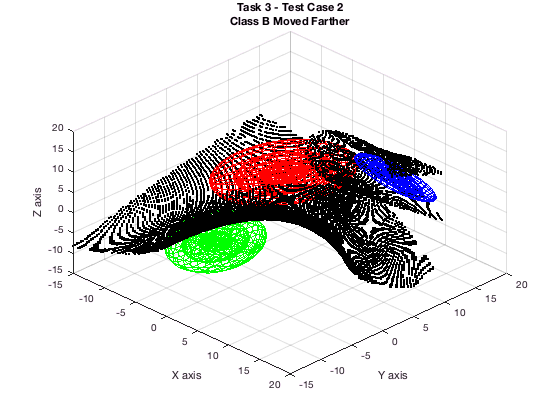

% Test Case 2 
% Moving class B away from class A by changing its mean

t3_2_mu_B = [12 10 10];
t3_2_data_B = gaussian_data_from_ss(K,D,t3_2_mu_B,sigma_B); % Re generating Class B with new mean
t3_2_pdfB = gaus_pdf(t3_2_data_B,volume); % A vector of probabilities that each point is from the new class B

t3_priors = [1/3, 1/3, 1/3];
[t3_2_gA, t3_2_gB, t3_2_gC] = discriminant(pdfA, t3_2_pdfB, pdfC, t3_priors);
[t3_2_b_AB, t3_2_b_BC, t3_2_b_CA] = boundaries(t3_2_gA, t3_2_gB, t3_2_gC,volume);

figure(3)
visualize_boundary(data_A, t3_2_data_B, data_C, t3_2_b_AB, t3_2_b_BC, t3_2_b_CA);
title({'Task 3 - Test Case 2', 'Class B Moved Farther'})


clear t3_2_data_B t3_2_pdfB t3_priors t3_2_gA t3_2_gB t3_2_gC t3_2_b_AB t3_2_b_BC t3_2_b_CA

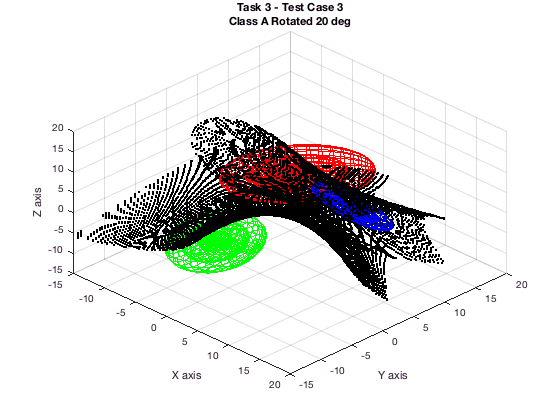

% Test Case 3 
% Rotating class A by 20 degrees
rotx = @(t) [1 0 0; 0 cosd(t) -sind(t) ; 0 sind(t) cosd(t)] ;
roty = @(t) [cosd(t) 0 sind(t) ; 0 1 0 ; -sind(t) 0  cosd(t)] ;
rotz = @(t) [cosd(t) -sind(t) 0 ; sind(t) cosd(t) 0 ; 0 0 1] ;
t3_3_data_A = data_A*rotx(20);
t3_3_pdfA = gaus_pdf(t3_3_data_A, volume);

t3_priors = [1/3, 1/3, 1/3];
[t3_3_gA, t3_3_gB, t3_3_gC] = discriminant(t3_3_pdfA, pdfB, pdfC, t3_priors);
[t3_3_b_AB, t3_3_b_BC, t3_3_b_CA] = boundaries(t3_3_gA, t3_3_gB, t3_3_gC,volume);

figure(4)
visualize_boundary(t3_3_data_A, data_B, data_C, t3_3_b_AB, t3_3_b_BC, t3_3_b_CA);
title({'Task 3 - Test Case 3', 'Class A Rotated 20 deg'})


clear t3_3_data_B t3_3_pdfB t3_priors t3_3_gA t3_3_gB t3_3_gC t3_3_b_AB t3_3_b_BC t3_3_b_CA

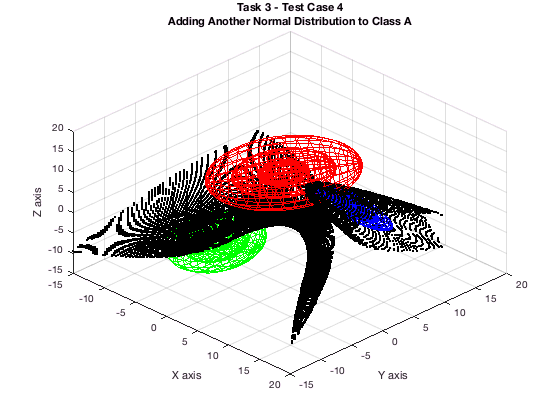

% Test Case 4 
% Adding a normal distribution to data A
t3_4_data_A = data_A + randn(K,D);
t3_4_pdfA = gaus_pdf(t3_4_data_A, volume);

t3_priors = [1/3, 1/3, 1/3];
[t3_4_gA, t3_4_gB, t3_4_gC] = discriminant(t3_4_pdfA, pdfB, pdfC, t3_priors);
[t3_4_b_AB, t3_4_b_BC, t3_4_b_CA] = boundaries(t3_4_gA, t3_4_gB, t3_4_gC,volume);

figure(5)
visualize_boundary(t3_4_data_A, data_B, data_C, t3_4_b_AB, t3_4_b_BC, t3_4_b_CA);
title({'Task 3 - Test Case 4', 'Adding Another Normal Distribution to Class A'})


clear t3_4_data_B t3_4_pdfB t3_priors t3_4_gA t3_4_gB t3_4_gC t3_4_b_AB t3_4_b_BC t3_4_b_CA

**Task 4** - Assess how these decision boundaries change with changes to the three class’s a priori probabilities.

Solution: 

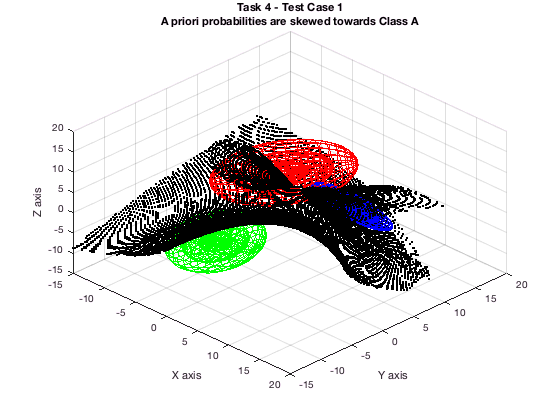

% Test case 1 
% A priori probabilities are skewed greatly towards Class A 
t4_1_priors = [7/8 1/16 1/16];
[t4_1_gA, t4_1_gB, t4_1_gC] = discriminant(pdfA, pdfB, pdfC, t4_1_priors);
[t4_1_b_AB, t4_1_b_BC, t4_1_b_CA] = boundaries(t4_1_gA, t4_1_gB, t4_1_gC,volume);

figure(6)
visualize_boundary(data_A, data_B, data_C, t4_1_b_AB, t4_1_b_BC, t4_1_b_CA);
title({'Task 4 - Test Case 1', 'A priori probabilities are skewed towards Class A'})


clear t4_1_data_B t4_1_pdfB t3_priors t4_1_gA t4_1_gB t4_1_gC t4_1_b_AB t4_1_b_BC t4_1_b_CA

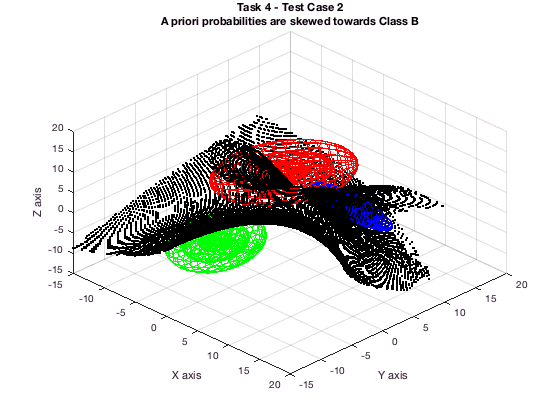

% Test case 2 
% A priori probabilities are skewed greatly towards Class B
t4_2_priors = [7/8 1/16 1/16];
[t4_2_gA, t4_2_gB, t4_2_gC] = discriminant(pdfA, pdfB, pdfC, t4_2_priors);
[t4_2_b_AB, t4_2_b_BC, t4_2_b_CA] = boundaries(t4_2_gA, t4_2_gB, t4_2_gC,volume);

figure(7)
visualize_boundary(data_A, data_B, data_C, t4_2_b_AB, t4_2_b_BC, t4_2_b_CA);
title({'Task 4 - Test Case 2', 'A priori probabilities are skewed towards Class B'})


clear t4_2_data_B t4_2_pdfB t3_priors t4_2_gA t4_2_gB t4_2_gC t4_2_b_AB t4_2_b_BC t4_2_b_CA

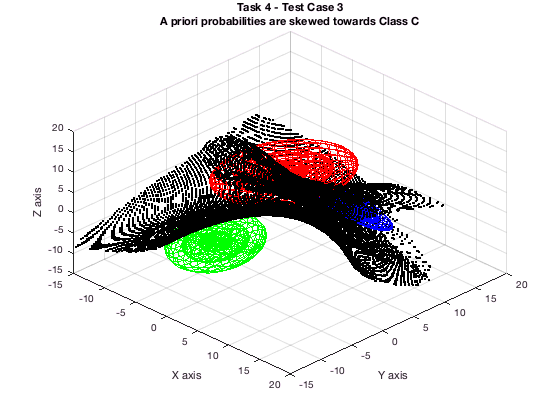

% Test case 3
% A priori probabilities are skewed greatly towards Class C
t4_3_priors = [1/16 1/16 7/8]; 
[t4_3_gA, t4_3_gB, t4_3_gC] = discriminant(pdfA, pdfB, pdfC, t4_3_priors);
[t4_3_b_AB, t4_3_b_BC, t4_3_b_CA] = boundaries(t4_3_gA, t4_3_gB, t4_3_gC,volume);

figure(8)
visualize_boundary(data_A, data_B, data_C, t4_3_b_AB, t4_3_b_BC, t4_3_b_CA);
title({'Task 4 - Test Case 3', 'A priori probabilities are skewed towards Class C'})


clear t4_3_data_B t4_3_pdfB t3_priors t4_3_gA t4_3_gB t4_3_gC t4_3_b_AB t4_3_b_BC t4_3_b_CA

** Comments: **

We can see with this dataset changes to the a priori probability, unless taken to the extreme, do not have much of an impact on the decision boundaries. This is because the original decision boundaries lie quite far away (at least 3 standard deviations) from the mean of the original datasets . If we were to adjust the datasets to be closer together such that the decison boundaries are within fewer standard deviations of the mean we should notice that the decision boundaries become much more sensitive to changes in the a priori probabilies. 

**Task 5 **-  Assess how these decision boundaries change with changes to the classes λAA, λAB, λAC, λBB, λBC, and, λCC loss functions, assuming λAB = λBA, λAC = λCA and λBC = λCB.

% A priori probabilities 
pwA = 0.3;
pwB = 0.3;
pwC = 0.3;

% Evidence
px = pdfA*pwA + pdfB*pwB + pdfC*pwC;

% Bayes theorem for posteriori
pwAx = (pdfA*pwA)./px;
pwBx = (pdfB*pwB)./px;
pwCx = (pdfC*pwC)./px;

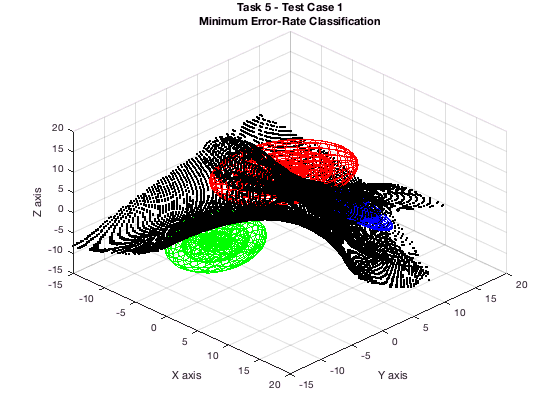

% Test Case 1 
% Loss functions for minimum error rate classification:
t5_1_lAA = 0;
t5_1_lBB = 0;
t5_1_lCC = 0;
t5_1_lAB = 1;
t5_1_lBA = t5_1_lAB;
t5_1_lAC = 1;
t5_1_lCA = t5_1_lAC;
t5_1_lBC = 1;
t5_1_lCB = t5_1_lBC;

% Calculate risk
t5_1_RAx = t5_1_lAA*pwAx + t5_1_lAB*pwBx + t5_1_lAC*pwCx;
t5_1_RBx = t5_1_lBA*pwAx + t5_1_lBB*pwBx + t5_1_lBC*pwCx;
t5_1_RCx = t5_1_lCA*pwAx + t5_1_lCB*pwBx + t5_1_lCC*pwCx;

% Calculate discriminant 
t5_1_gA = -log(t5_1_RAx);
t5_1_gB = -log(t5_1_RBx);
t5_1_gC = -log(t5_1_RCx);

[t5_1_b_AB, t5_1_b_BC, t5_1_b_CA] = boundaries(t5_1_gA, t5_1_gB, t5_1_gC,volume);

figure(9)
visualize_boundary(data_A, data_B, data_C, t5_1_b_AB, t5_1_b_BC, t5_1_b_CA);
title({'Task 5 - Test Case 1', 'Minimum Error-Rate Classification'})


clear t5_1_lAA t5_1_lBB t5_1_lCC t5_1_lAB t5_1_lBA t5_1_lAC t5_1_lCA t5_1_lBC t5_1_lCB t5_1_RAx t5_1_RBx t5_1_RCx t5_1_gA t5_1_gB t5_1_gC t5_1_b_AB t5_1_b_BC t5_1_b_CA

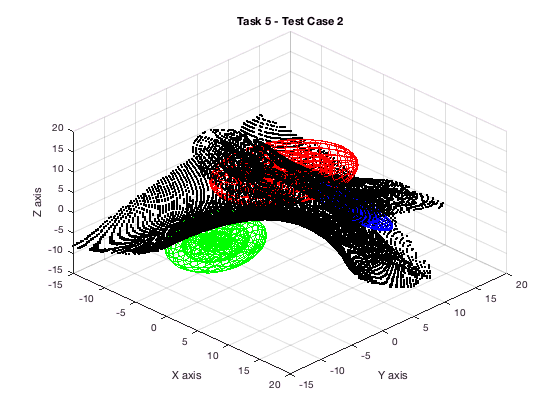

% Test Case 2
% Loss functions 
t5_2_lAA = 0;
t5_2_lBB = 0;
t5_2_lCC = 0;
t5_2_lAB = 1000;
t5_2_lBA = t5_2_lAB;
t5_2_lAC = 1;
t5_2_lCA = t5_2_lAC;
t5_2_lBC = 1;
t5_2_lCB = t5_2_lBC;

% Calculate risk
t5_2_RAx = t5_2_lAA*pwAx + t5_2_lAB*pwBx + t5_2_lAC*pwCx;
t5_2_RBx = t5_2_lBA*pwAx + t5_2_lBB*pwBx + t5_2_lBC*pwCx;
t5_2_RCx = t5_2_lCA*pwAx + t5_2_lCB*pwBx + t5_2_lCC*pwCx;

% Calculate discriminant 
t5_2_gA = -log(t5_2_RAx);
t5_2_gB = -log(t5_2_RBx);
t5_2_gC = -log(t5_2_RCx);

[t5_2_b_AB, t5_2_b_BC, t5_2_b_CA] = boundaries(t5_2_gA, t5_2_gB, t5_2_gC,volume);

figure(10)
visualize_boundary(data_A, data_B, data_C, t5_2_b_AB, t5_2_b_BC, t5_2_b_CA);
title({'Task 5 - Test Case 2'})


clear t5_2_lAA t5_2_lBB t5_2_lCC t5_2_lAB t5_2_lBA t5_2_lAC t5_2_lCA t5_2_lBC t5_2_lCB t5_2_RAx t5_2_RBx t5_2_RCx t5_2_gA t5_2_gB t5_2_gC t5_2_b_AB t5_2_b_BC t5_2_b_CA


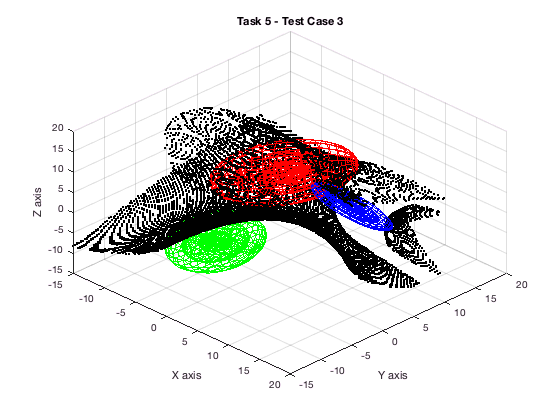

% Test Case 3
% Loss functions
t5_3_lAA = 0;
t5_3_lBB = 0;
t5_3_lCC = 0;
t5_3_lAB = 10000000000;
t5_3_lBA = t5_3_lAB;
t5_3_lAC = 0.00001;
t5_3_lCA = t5_3_lAC;
t5_3_lBC = 0.00001;
t5_3_lCB = t5_3_lBC;

% Calculate risk
t5_3_RAx = t5_3_lAA*pwAx + t5_3_lAB*pwBx + t5_3_lAC*pwCx;
t5_3_RBx = t5_3_lBA*pwAx + t5_3_lBB*pwBx + t5_3_lBC*pwCx;
t5_3_RCx = t5_3_lCA*pwAx + t5_3_lCB*pwBx + t5_3_lCC*pwCx;

% Calculate discriminant 
t5_3_gA = -log(t5_3_RAx);
t5_3_gB = -log(t5_3_RBx);
t5_3_gC = -log(t5_3_RCx);

[t5_3_b_AB, t5_3_b_BC, t5_3_b_CA] = boundaries(t5_3_gA, t5_3_gB, t5_3_gC,volume);

figure(11)
visualize_boundary(data_A, data_B, data_C, t5_3_b_AB, t5_3_b_BC, t5_3_b_CA);
title({'Task 5 - Test Case 3'})


clear t5_3_lAA t5_3_lBB t5_3_lCC t5_3_lAB t5_3_lBA t5_3_lAC t5_3_lCA t5_3_lBC t5_3_lCB t5_3_RAx t5_3_RBx t5_3_RCx t5_3_gA t5_3_gB t5_3_gC t5_3_b_AB t5_3_b_BC t5_3_b_CA


**Comments: **One can interpret the use of the losses as a way to increase the prior probability for specific classes which are more important than others. Higher losses indicate no points will be assigned to that class. When we see class 3, the Risk associated with A and B is significantly higher with respect to risk associated with C. Hence, several points from class B and C from original plot of points have been classified to class C.

Simmilarly to changes in a priori probability, without taking using extreme values as loss functions there is little change seen in the decision boundaries. This is once again a result of the spread of the original datasets and If we were to adjust the datasets to be closer together we should notice that the decision boundaries become much more sensitive to changes in the loss functions. 

**Task 6 ** -  Now introduce outlier data points to one of the classes at a 10, 50, and 100 standard deviation  Mahalanobis distance from that class’s mean and regenerate the Bayes class boundaries.

Solution:

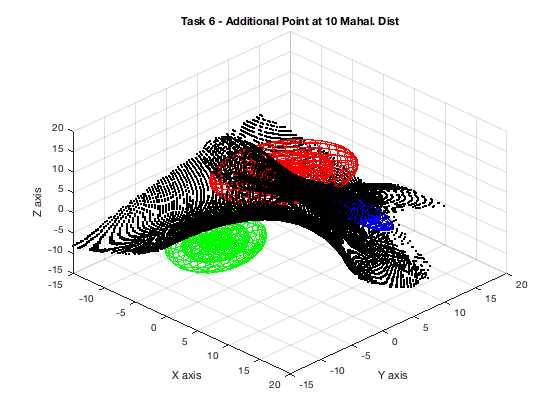

% Adding these points to Class B
t6_priors = [1/3 1/3 1/3];

% New point at 10 stdev 
pt_mal_10 = additional_pts(mu_B, sigma_B, 10)'; % Finding a point at the desired mahalanobis distance 
class_B_p10 = [data_B;pt_mal_10]; % Adding the new point to the original dataset A 
pdfB_p10 = gaus_pdf(class_B_p10, volume); % Calculating the pdf for the new dataset 

[gA_p10, gB_p10, gC_p10] = discriminant(pdfA, pdfB_p10, pdfC, t6_priors);
[b_AB_p10, b_BC_p10, b_CA_p10] = boundaries(gA_p10, gB_p10, gC_p10,volume);

figure(12)
visualize_boundary(data_A, class_B_p10, data_C, b_AB_p10, b_BC_p10, b_CA_p10);
title({'Task 6 - Additional Point at 10 Mahal. Dist'})


clear class_B_p10 pdfA_p10 gA_p10 gB_p10 gC_p10 b_AB_p10 b_BC_p10 b_CA_p10

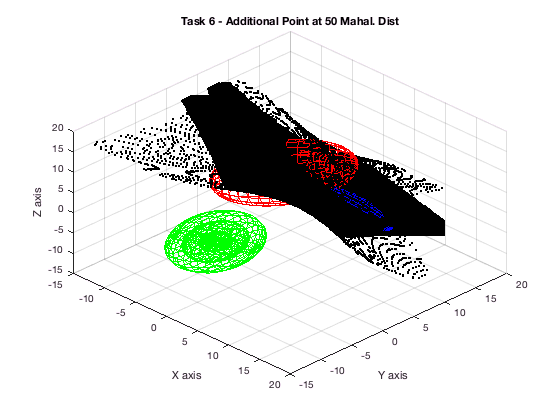

% New point at 50 stdev 
pt_mal_50 = additional_pts(mu_B, sigma_B, 50)'; % Finding a point at the desired mahalanobis distance 
class_B_p50 = [data_B;pt_mal_50]; % Adding the new point to the original dataset A 
pdfB_p50 = gaus_pdf(class_B_p50, volume); % Calculating the pdf for the new dataset 

[gA_p50, gB_p50, gC_p50] = discriminant(pdfB_p50, pdfB, pdfC, t6_priors);
[b_AB_p50, b_BC_p50, b_CA_p50] = boundaries(gA_p50, gB_p50, gC_p50,volume);

figure(13)
visualize_boundary(data_A, class_B_p50, data_C, b_AB_p50, b_BC_p50, b_CA_p50);
title({'Task 6 - Additional Point at 50 Mahal. Dist'})


clear class_B_p50 pdfA_p50 gA_p50 gB_p50 gC_p50 b_AB_p50 b_BC_p50 b_CA_p50

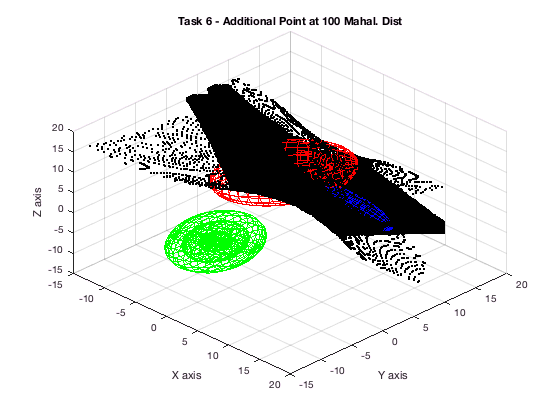

% New point at 100 stdev
pt_mal_100 = additional_pts(mu_B, sigma_B, 100)'; % Finding a point at the desired mahalanobis distance 
class_B_p100 = [data_B;pt_mal_100]; % Adding the new point to the original dataset A 
pdfB_p100 = gaus_pdf(class_B_p100, volume); % Calculating the pdf for the new dataset 

[gA_p100, gB_p100, gC_p100] = discriminant(pdfB_p100, pdfB, pdfC, t6_priors);
[b_AB_p100, b_BC_p100, b_CA_p100] = boundaries(gA_p100, gB_p100, gC_p100,volume);

figure(14)
visualize_boundary(data_A, class_B_p100, data_C, b_AB_p100, b_BC_p100, b_CA_p100);
title({'Task 6 - Additional Point at 100 Mahal. Dist'})


clear class_B_p100 pdfA_p100 gA_p100 gB_p100 gC_p100 b_AB_p100 b_BC_p100 b_CA_p100

**Comments: **

As shown above the simple addition of a single outlier data point to a class can cause a large shift in the inter-class Bayes decision boundaries. A single data point can shift the mean, covarriance or higher order statistics of a given classe. Since we know that inter-class boundaries are statistics of the datasets themselves (their mean and covariance will affect the nature of the boundary) it makes sense that a shift to any of these statistics would cause a shift in the inter-class boundaries we observe. 

**Task 7:** For real-world data analysis problems,

**(a) Could the nature of the class decision boundaries effective be driven by only a few data points within the data?**

Yes, the nature of the class decision boundaries can be effectively driven by only a few data points. Adding or removing new data points to the class could change the mean, covariance and other higher order statistics. As the order of the statistics increases it is more sensitive to the data since an $n^{th}$ order statistic depends on the $n^{th}$order of data . Adding Hard inliers can cause significant change in the decision boundaries. Outliers could make the boundaries worse, as  they differ significantly from the statistics of the class.

**(b) Is it correct (or appropriate) to have decision boundaries that exhibit high sensitivities to only a small number of data samples?**

Well it depends on the situation and the application.  We cannot make a system that can detect all outliers. Some techniques can detect one outlier or a specific set of outliers but there is no technique available that can detect all outliers. (No free lunch and Ugly Duckling theorem). Not to forget, the trade off between bias and variance, with a high variance classifier you can have decision boundaries not much sensitive to noise thereby increasing the chance of overfitting the data. Like wise , high bias we can tend to make a simpler model , that may underfit the data and eliminate data points that may play a significant role in determining the distribution of the decision boundary and make not account of enough variability.

**(c) How would you detect this?**

If the underlying distribution of the datasamples in the class is Gaussian,  standard deviation of the sample can be used as a cut off to identify such data samples . Three standard deviations from the mean is a common cut-off in practice for identifying outliers in a Gaussian or Gaussian-like distribution.

An approach to detect outliers ( particularly useful in non-gaussian distribution) would be to take each feature vector in the data and plot its histogram.  The histogram doesnt depends on the moments ( which are data-sensitve) . A convenient definition of an oultier is a point that falls more than 1.5 times the interquartile range above the third quartile or below the first quartile.

Using automatic outlier detection of data using one- classification method. This involves fitting a model on what is supposed to be 'normal data' and applying predicition algorithms to decide whether new data is normal or an outlier. We can identify outliers by locating samples that far from the feature space, however with the increase in dimensions, curse of dimensionality kicks in and this method may not be that effective.

When dealing with time series data, outliers are usually the unexpected spikes or dips of observations at given points in time.

**(d) How would you resolve this?**

Creating a multistage classifier where first stage classifier, works on classifying normal data and the outliers and the second stage classifier works on classifying the actual data.

For time series data,

a) Median filter running on sliding windows of data.

b) Matched filter works on non-stationary data and more robust in detecting samples

c) Neural networks

d) Kalman filter for linear and for non-linear extended Kalman filter.

function[new_pt] = additional_pts(mu, sigma, desired_mah)
    [V, D] = eig(sigma);

    principal_axes = sqrt(desired_mah)*((V)*sqrt(D))+mu'; % Principal axes extended to the appropriate length to acheive desired mahalanobis disance
    new_pt = principal_axes(:,1); % Choosing the new point along the 1st principal axes ( this choice is arbatrary)    

end

function[discA, discB, discC] = discriminant(pdfA,pdfB, pdfC, prior)
    discA = log(pdfA)+log(prior(1)); % Calculate the discriminant for points belonging to Class A
    discB = log(pdfB)+log(prior(2)); % Calculate the discriminant for points belonging to Class B
    discC = log(pdfC)+log(prior(3)); % Calculate the discriminant for points belonging to Class C
end 


function [pdf] = gaus_pdf(class ,X)
    %finds the gaussian pdf 
    mu = mean(class); 
    sigma = cov(class); 
    [~,d] = size(X);
    X0 = bsxfun(@minus,X,mu);
    [R,~] = cholcov(sigma,0);
    xRinv = X0 / R;
    % determinant of sigma is product of diagonal elements of cholesky decomposition
    logSqrtDetSigma = sum(log(diag(R))); 
    quadratic = sum(xRinv.^2, 2);
    pdf = exp(-0.5*quadratic - logSqrtDetSigma - d*log(2*pi)/2);
end


function f = gaussian_data_from_ss(K,D,mu,sigma)
    N = randn(K,D); % Generate a subset of K D-dimensional samples from a normal distribution
    N_c = N - mean(N); % Centralize the data at zero-mean
    
    [v,d] = eig(cov(N_c)); % Obtain eigen values and eigen vectors for covariance of N    
    R = v*inv(sqrt(d)); % Generate the whitening transform
    W  = N_c*R; % Apply the whitening transform on the centralized data
    
    [vn,dn] = eig(sigma); % Obtain eigen values and eigen vectors of the desired covariance
    R_inv = sqrt(dn)*inv(vn); % Generate the inverse whitening transform
    f = W*R_inv; % Apply the inverse whitening transfrom on the whitened gaussian data 
    f = f + mu; % Centralize the data at the desired mu
end 

function V = vol3D(Vaxis,Num) 
    NV = Num;
    
    if length(Vaxis) == 2
        Vaxis = [Vaxis Vaxis Vaxis];
    end
    
    min_a = Vaxis(1);
    max_a = Vaxis(2);
    res = (max_a-min_a)/(NV-1);
    
    r = min_a:res:max_a;
    r = r(:);
    
    rx = [Vaxis(1):(Vaxis(2)-Vaxis(1))/(NV-1):Vaxis(2)]';
    ry = [Vaxis(3):(Vaxis(4)-Vaxis(3))/(NV-1):Vaxis(4)]';
    rz = [Vaxis(5):(Vaxis(6)-Vaxis(5))/(NV-1):Vaxis(6)]';
    
    x = zeros(3,length(rz)^3);
    k =1;
    j = 1;
    for i = 1:length(rz):length(x)
        x(3,(i-1)+(1:length(rz)))= rz;
        x(2,(i-1)+(1:length(rz))) = ry(k)*ones(1,length(rz));
        x(1,(i-1)+(1:length(rz))) = rx(j)*ones(1,length(rz));
        k = k+1;
        if k > length(rz)
            k =1;
            j = j +1;
        end
    end
    x = x';
    V = x;

end

function [b_AB, b_BC, b_AC] = boundaries(gA, gB, gC,V)
    %pairwise testing has to be done between two classes than have g higher
    %than the third
    indxAB = find((gA>gB & gB>gC)|(gB>gA & gA>gC));
    indxBC = find((gB>gC & gC>gA)|(gC>gB & gB>gA));
    indxAC = find((gA>gC & gC>gB)|(gC>gA & gA>gB));
    
    gAB = abs(gA(indxAB) - gB(indxAB));
    gBC = abs(gB(indxBC) - gC(indxBC));
    gAC = abs(gA(indxAC) - gC(indxAC));
    
    %tolerence 0.1
    indxAB_n = find(gAB<0.1);
    indxBC_n = find(gBC<0.1);
    indxAC_n = find(gAC<0.1);
    indxAB = indxAB(indxAB_n);
    indxBC = indxBC(indxBC_n);
    indxAC = indxAC(indxAC_n);
    
    b_AB = V(indxAB,:);
    b_BC = V(indxBC,:);
    b_AC = V(indxAC,:);

end

function [x1,y1,z1,x2,y2,z2,x3,y3,z3] = ellipse_cord(data)

    mu = mean(data);
    sigma = cov(data);
    [v,d] = eig(sigma);
    %plot ellipsoid for three standard deviations and zero mean
    radius = sqrt(diag(d));
    [x1,y1,z1] = ellipsoid(0, 0, 0, radius(1),radius(2),radius(3));
    [x2,y2,z2] = ellipsoid(0, 0, 0, 2*radius(1),2*radius(2),2*radius(3));
    [x3,y3,z3] = ellipsoid(0, 0, 0, 3*radius(1),3*radius(2),3*radius(3));
    
    %rotate ellipsoids
    x1 = kron(v(:,1),x1);y1 = kron(v(:,2),y1);z1 = kron(v(:,3),z1);
    x2 = kron(v(:,1),x2);y2 = kron(v(:,2),y2);z2 = kron(v(:,3),z2);
    x3 = kron(v(:,1),x3);y3 = kron(v(:,2),y3);z3 = kron(v(:,3),z3);
    dat1 = x1 + y1 + z1; dat2 = x2 + y2 + z2 ; dat3 = x3 + y3 + z3; % to account for rotation of all three axis 
    n = size(dat1,2);
    
    %shift the ellipsoids
    x1 = dat1(1:n,:) + mu(1); y1 = dat1(n+1:2*n,:) + mu(2); z1 = dat1(2*n+1:end,:) + mu(3); 
    x2 = dat2(1:n,:) + mu(1); y2 = dat2(n+1:2*n,:) + mu(2); z2 = dat2(2*n+1:end,:) + mu(3);
    x3 = dat3(1:n,:) + mu(1); y3 = dat3(n+1:2*n,:) + mu(2); z3 = dat3(2*n+1:end,:) + mu(3);
       
end 

function axes_plot = visualize_boundary(data_A, data_B, data_C, b_AB, b_BC, b_CA)

    mu_A = mean(data_A);
    mu_B = mean(data_B);
    mu_C = mean(data_C);

    sigma_A = cov(data_A);
    sigma_B = cov(data_B);
    sigma_C = cov(data_C);

    [vA,dA] = eig(sigma_A);
    [vB,dB] = eig(sigma_B);
    [vC,dC] = eig(sigma_C);

    axes_plot = axes;
    hold(axes_plot,'on');
    
    [xA1,yA1,zA1,xA2,yA2,zA2,xA3,yA3,zA3] = ellipse_cord(data_A);
    surf(xA1, yA1, zA1,'EdgeColor', 'r','FaceAlpha',0);
    surf(xA2, yA2, zA2, 'EdgeColor', 'r','FaceAlpha',0);
    surf(xA3, yA3, zA3,'EdgeColor', 'r','FaceAlpha',0);
   
    [xB1,yB1,zB1,xB2,yB2,zB2,xB3,yB3,zB3] = ellipse_cord(data_B);
    surf(xB1, yB1, zB1,'EdgeColor', 'b','FaceAlpha',0);
    surf(xB2, yB2, zB2, 'EdgeColor', 'b','FaceAlpha',0);
    surf(xB3, yB3, zB3,'EdgeColor', 'b','FaceAlpha',0);
   
    [xC1,yC1,zC1,xC2,yC2,zC2,xC3,yC3,zC3] = ellipse_cord(data_C);
    surf(xC1, yC1, zC1,'EdgeColor', 'g','FaceAlpha',0);
    surf(xC2, yC2, zC2, 'EdgeColor', 'g','FaceAlpha',0);
    surf(xC3, yC3, zC3,'EdgeColor', 'g','FaceAlpha',0);

    %plot decision boundaries
    plot3(b_AB(:,1),b_AB(:,2),b_AB(:,3),'Marker','.','LineStyle','none','Color','k');
    plot3(b_BC(:,1),b_BC(:,2),b_BC(:,3),'Marker','.','LineStyle','none','Color','k');
    plot3(b_CA(:,1),b_CA(:,2),b_CA(:,3),'Marker','.','LineStyle','none','Color','k');

    % Create zlabel
    zlabel('Z axis');

    % Create ylabel
    ylabel('Y axis');

    % Create xlabel
    xlabel('X axis');

    xlim(axes_plot,[-15 20]);
    ylim(axes_plot,[-15 20]);
    zlim(axes_plot,[-15 20]);
    view(axes_plot,[45 45]);
    grid(axes_plot,'on');
    hold(axes_plot,'off');
end
